A = A(:);
%CREATING THE NORMALIZED HISTOGRAM (FIRST LETTER IS THE DATA ALWAYS)
clf;
hold on;
LegHandles = []; LegText = {};



[CdfF,CdfX] = ecdf(A,'Function','cdf'); 
BinInfo.rule = 1;
[~,BinEdge] = internal.stats.histbins(A,[],[],BinInfo,CdfF,CdfX);
[BinHeight,BinCenter] = ecdfhist(CdfF,CdfX,'edges',BinEdge);
hLine = bar(BinCenter,BinHeight,'hist');
set(hLine,'FaceColor','none','EdgeColor',[0.333333 0 0.666667],...
    'LineStyle','-', 'LineWidth',1);
xlabel('Data');
ylabel('Density')
LegHandles(end+1) = hLine;
LegText{end+1} = 'data';

XLim = get(gca,'XLim');
XLim = XLim + [-1 1] * 0.01 * diff(XLim);
XContinuous = linspace(XLim(1),XLim(2),100);
XIncr = max(1,floor((XLim(2)-XLim(1))/100));
XDiscrete = floor(XLim(1)):XIncr:ceil(XLim(2));
%CREATING ERRORBARS
elements=[3 14 15 21 24 14 6 2 0  1];
normalizedelements=[0.01 0.046 0.05 0.07 0.08 0.046 0.02 0.006 0  0.003];
bincenters= 16.5:3:43.5;
err=sqrt(elements)/300;
bar(bincenters, normalizedelements);

errorbar(bincenters,normalizedelements, err,'o');

%POISSON
pd1 = fitdist(A, 'poisson')

pd1 =   PoissonDistribution

  Poisson distribution
    lambda = 25.93   [24.932, 26.928]


XGrid = XDiscrete;
YPlot = pdf(pd1,XGrid);
hLine = plot(XGrid,YPlot,'Color',[1 0 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','+', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'poisson';
%GAUSS

pd2 = fitdist(A, 'normal')

pd2 =   NormalDistribution

  Normal distribution
       mu =   25.93   [24.917, 26.943]
    sigma = 5.10546   [4.48263, 5.93089]


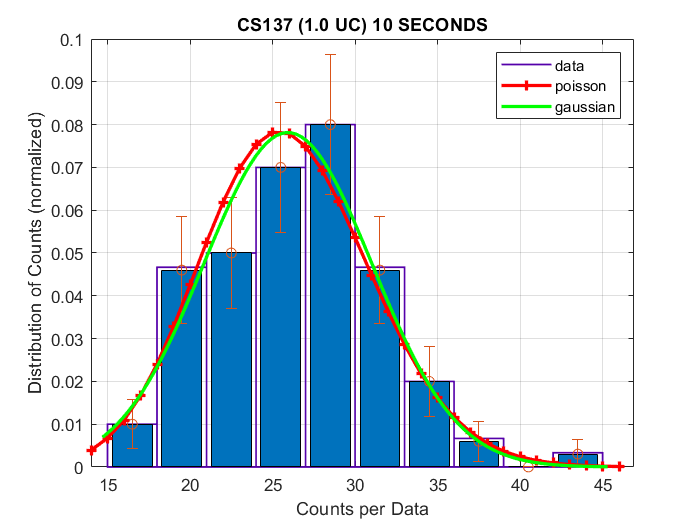

XGrid = XContinuous;
YPlot = pdf(pd2,XGrid);
hLine = plot(XGrid,YPlot,'Color',[0 1 0],...
    'LineStyle','-', 'LineWidth',2,...
    'Marker','none', 'MarkerSize',6);
LegHandles(end+1) = hLine;
LegText{end+1} = 'gaussian';

grid on;
box on;
hold off;


hLegend = legend(LegHandles,LegText,'Orientation', 'vertical', 'FontSize', 9, 'Location', 'northeast');
set(hLegend,'Interpreter','none');

xlim([14.0 46.9])
ylim([0 0.100])
title('CS137 (1.0 UC) 10 SECONDS')
xlabel('Counts per Data')
ylabel('Distribution of Counts (normalized)')